## This is the estimated transformation from the grid to the tool:

tcp = [eul2rotm([0,0,pi]),[185;100;0]];
tcp = [tcp;[0,0,0,1]]

tcp =     1.0000         0         0  185.0000
         0   -1.0000   -0.0000  100.0000
         0    0.0000   -1.0000         0
         0         0         0    1.0000


## This is the known transformation from the camera to the grid:

grid =     [-0.00500405, 0.99998434, 0.0025046; -0.9306746, -0.00374094, -0.36582892; -0.36581382, -0.00416159, 0.93067875];
grid = [grid,[151.48231455772967; -45.84279051621655; 1140.7020382437486]];
grid = [grid;[0,0,0,1]]

grid =    1.0e+03 *

   -0.0000    0.0010    0.0000    0.1515
   -0.0009   -0.0000   -0.0004   -0.0458
   -0.0004   -0.0000    0.0009    1.1407
         0         0         0    0.0010


## This is the estimated transformation from the camera to the tcp:

cam2tcp = grid*tcp

cam2tcp =    1.0e+03 *

   -0.0000   -0.0010   -0.0000    0.2506
   -0.0009    0.0000    0.0004   -0.2184
   -0.0004    0.0000   -0.0009    1.0726
         0         0         0    0.0010


## Transformation from base to TCP, taken from UR Robot:

rodriguesRob2TCP = [-1.9105601255822304, -0.7122081854735294, -1.7149345420446338];
translationRob2TCP = [0.153729588554069, 0.36785194956032446, 0.898024694368065].*1000;
mag = sqrt(rodriguesRob2TCP(1)^2 + rodriguesRob2TCP(2)^2 + rodriguesRob2TCP(3)^2);
norm = rodriguesRob2TCP./mag;
rotRob2TCP = vrrotvec2mat([norm, mag]);
Rob2TCP = [rotRob2TCP, translationRob2TCP'];
Rob2TCP = [Rob2TCP;[0,0,0,1]]

Rob2TCP =     0.0827    0.6576    0.7488  153.7296
    0.0663   -0.7533    0.6543  367.8519
    0.9944   -0.0045   -0.1059  898.0247
         0         0         0    1.0000


Invert and and apply to the grid tcp:

cam2base = cam2tcp*inv(Rob2TCP)

cam2base =    1.0e+03 *

   -0.0007    0.0008   -0.0000    0.0758
    0.0002    0.0002   -0.0010    0.5525
   -0.0007   -0.0006   -0.0003    1.6562
         0         0         0    0.0010


## Find true transformation from camera to robot base:

need our base estimate in meters:

cam2base_meters = cam2base;
cam2base_meters(1:3,4)=cam2base_meters(1:3,4)./1000

cam2base_meters =    -0.6599    0.7513   -0.0002    0.0758
    0.1994    0.1749   -0.9642    0.5525
   -0.7244   -0.6363   -0.2652    1.6562
         0         0         0    1.0000


Need to convert data from the robot to rotation matricies:

data = convert_rob_data('correspondences.json');

Good to take a look at atleast one point:

data(:,:,1)

ans =     0.0827    0.6576    0.7488    0.1537
    0.0663   -0.7533    0.6543    0.3679
    0.9944   -0.0045   -0.1059    0.8980
         0         0         0    1.0000


Need to invert checkerboard to tcp estimate:

endEst = tcp;
endEst(1:3,4) = endEst(1:3,4)./1000

endEst =     1.0000         0         0    0.1850
         0   -1.0000   -0.0000    0.1000
         0    0.0000   -1.0000         0
         0         0         0    1.0000


## Calibration

With example data:

Demo

Can now run code to find results

Starting Arm Calibration
Extracting Chessboards
Finding Camera Parameters
Running Optimization


Saving chessboard real and guess images


Error using matlab.graphics.shape.TextBox/set
There is no FaceColor property on the TextBox class.

Error in matlab.graphics.chart.internal.ctorHelper (line 6)
      set(obj, pvpairs{:});

Error in matlab.graphics.shape.TextBox

Error in annotation (

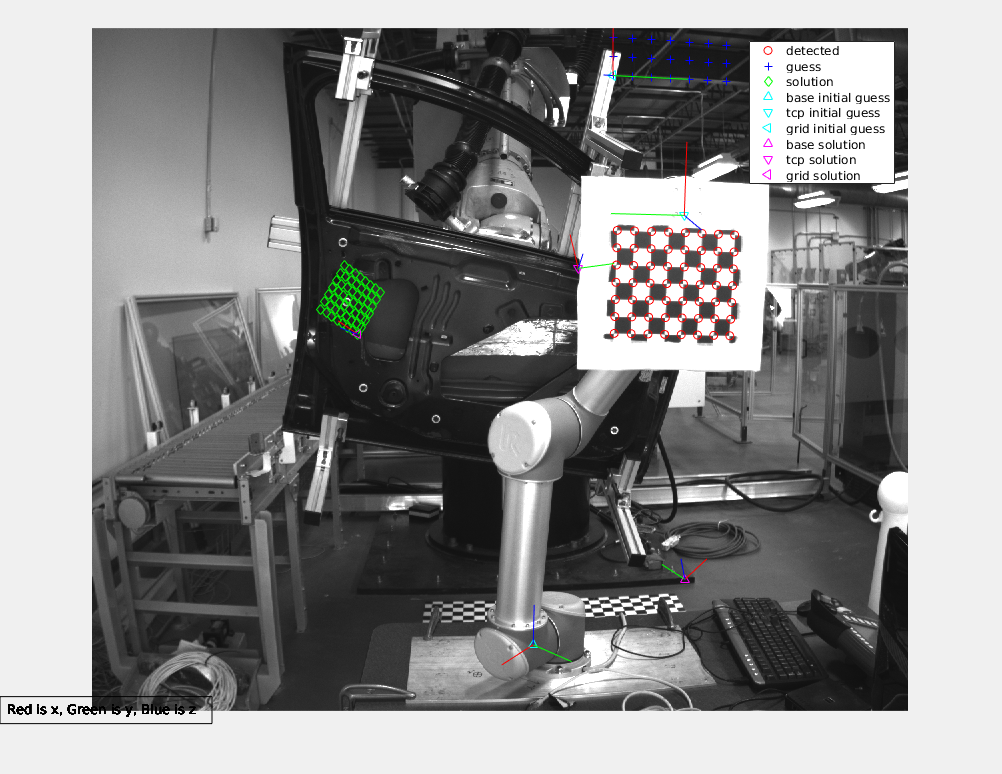

[TBase, TEnd, cameraParams, TBaseStd, TEndStd, pixelErr] = ...
    CalCamArm('Images',data,25.4,'errest',false,'maxBaseOffset', 2,...
    'baseEst', cam2base_meters, 'gripest', endEst)